% ------------------------------------------------
% UNIVERSIDADE TECNOLOGICA FEDERAL DO PARANA
% DEPARTAMENTO ACADEMICO DE ELETRONICA
%
% CONTROLE 1 - TRABALHO FINAL
%
% FABIO ZHAO YUAN WANG - 2358310
% VICTOR AUGUSTO DEL MONEGO - 2378345
%
% VALOR DE P = 5
% ------------------------------------------------

% comandos iniciais 
clear all
close all
clc

%Questão 1: Análise de Malha Aberta
% declarando o sistema
s = tf('s');
sys = (10*5)/(s*(s+5)*(0.1*s+5))

sys =
 
             50
  ------------------------
  0.1 s^3 + 5.5 s^2 + 25 s
 
Continuous-time transfer function.
Model Properties


zpk(sys)

ans =
 
       500
  --------------
  s (s+50) (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties



% polos e zeros
pole(sys)

ans =      0
   -50
    -5


%lugar das raízes

%Critério de estabilidade de routh Hurwitz
K = 1;
K_crit = 27.49;
sys_fb = feedback((K_crit)*sys,1)

sys_fb =
 
               1374
  -------------------------------
  0.1 s^3 + 5.5 s^2 + 25 s + 1374
 
Continuous-time transfer function.
Model Properties


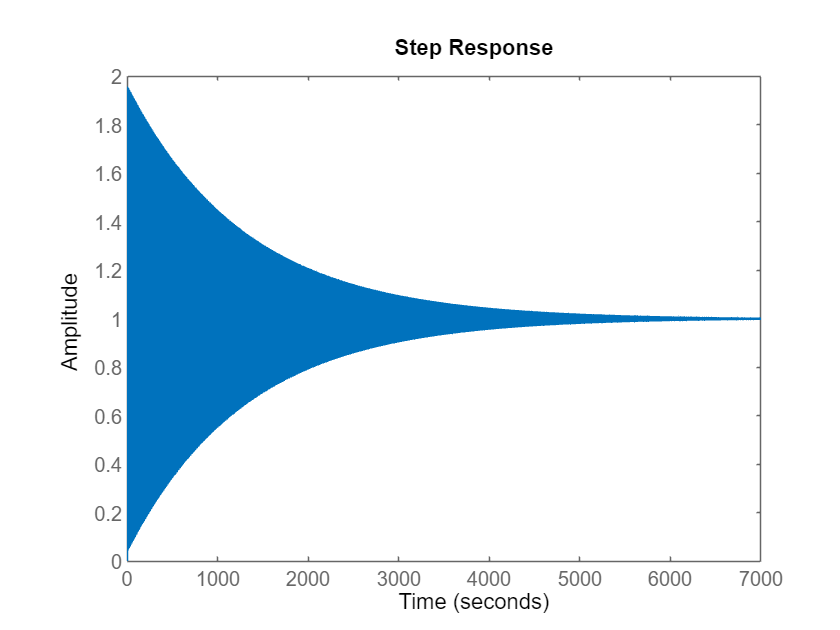

step(sys_fb)



%Constante de erro
%sistema é do tipo 1 (possui polo na origem)

Ktst = K_crit/2

Ktst = 13.7450

Kv = 10*Ktst*5/(5*5)

Kv = 27.4900

errv = 1/Kv

errv = 0.0364


% Visto que Kv é proporcional ao Ktst, e
% Kv é inversamente proporcional ao errv
% então, o único jeito de reduzir o erro associado à
% metade é dobrando o Kv, isto é, temos de
% dobrar o Ktst. Portanto, se reduzimos o erro à metade
% temos de dobrar o Ktst (I). Tendo (I) em mente:

% Para controladores com Ktst<K_routh/2,
% ao dobrar o valor de Ktst, garantimos a estabilidade
% já que 2*Ktst<K_routh, e, de (I) 
% conseguimos reduzir o erro à metade.

% Para controladores com K_routh/2 < Ktst < K_routh, 
% ao dobrarmos Ktst, afim de reduzir a metade
% o erro associado, não garantimos a
% estabilidade, já que K_routh < 2*Ktst.

%Questão 2: Controlador de avanço ou atraso de fase
%Primeiro, temos que definir o Kv









